# Signal-level simulations

This code performs a signal-space simulation of a digital communication scheme. It implements the following flowchart:

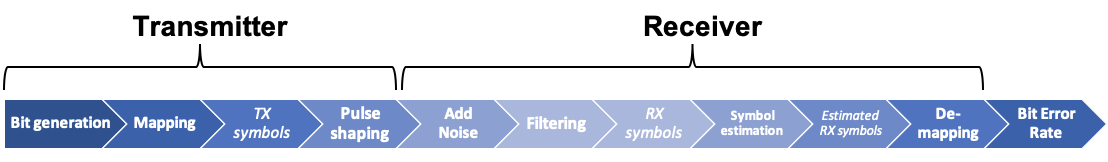

At the transmitter, the bits to be transmitted are mapped to complex symbols. Then a convolution between these symbols and the TX filter impulse response creates the baseband signal (i.e., complex envelope).

The channel is not considered in this simulation.

At the receiver, a thermal noise is added as a complex Additive White Gaussian Noise (AWGN) ensuring a given Signal-to-Noise (SNR) fixed as an input parameter. The received signal is then filtered (matched filter) to obtain the received symbols. The receiver estimates then the received noisy symbols and convert them back to bits (i.e., the demapping). The Bit Error Rate (BER) is eventually determined by comparing the transmitted with the received bits.

clc;                                        % Clear the command window screen
clear all;                                  % Erase all existing variables
close all;                                  % Close all figure windows

## Guidelines: what to do?

This code uses the following functions:

- mapping_QAM

- raised_cosine

- convolution_TX

- convolution_RX

- symbol_estimation_QAM

- demapping_QAM

The goal is to develop the missing code in the functions *convolution_TX* and *convolution_RX* . All the other functions have already been implemented in the 2 previous live scripts and should be reused here without any modifications.

Once all the functions are completed, you can observe the signals in time and frequency domains with respect to the input parameters of the communication scenario (e.g., roll-off factor, sps, span...). You can also plot the BER as a function of SNR.

**Tips:** to easily visualize the time domain waveforms, use a limited number of bits (e.g. 20bits with QPSK mapping). This will help you in finding buggs in your codes. The functions to perform the convolutions already exist in Matlab. You can therefore observe the final result you should reach and compare both the inbuilt Matlab function and your functions to see whether results fit or not. 

## Input parameters

nb_bit = 1e4 ;                              % Number of bits to be transmitted                          
nb_bit_per_symb = 4 ;                       % Number of bits per symbol
nb_symb = nb_bit / nb_bit_per_symb ;        % Number of transmitted symbols
snr_dB = 15 ;                               % Signal-to-Noise Ratio at RX (in dB)
rolloff = .5 ;                              % Roll-off factor
symb_rate = 100e6 ;                         % Symbol rate
sps = 4 ;                                   % Samples per symbol (oversampling ratio)
span = 16 ;                                 % Span of the pulse shaping filter

## Code variables

t_symb = 1 / symb_rate ;                    % Symbol duration
fs = symb_rate * sps ;                      % Sampling frequency 

**Comment**: The minimum sampling frequency *fs *depends in practice on the modulator architecture. With an analog IQ modulator architecture (see slides 20/21 course 3), $\text{sps}_{\text{min}}=1$ (i.e., *fs* = symbol rate for $\text{rolloff}=0$). With a digital IQ modulator architecture (see slide 22 course 3), $\text{sps}_{\text{min}}=2$ (i.e., *fs* = twice the symbol rate for $\text{rolloff}=0$). However in practice, an oversampling ratio is often used (e.g., $\text{sps}=16$). In this livescript, the *fs* is only used to create the time and frequency vectors in order to plot the waveforms and their spectrum. So *fs* is only defined for visualization purpose and is not used in the simulation per se (only $\text{sps}$ sets the number of samples per symbol).

## Transmitter (TX)

### Bit generation

bit_TX = randi( [0 1] , nb_bit , 1 ) ;                              % Random bit generation 

### Mapping

symb_TX = mapping_QAM( bit_TX , nb_bit_per_symb , nb_bit ) ;        % Map the input bits to complex symbols

### TX symbols: constellation plot (symbol space)

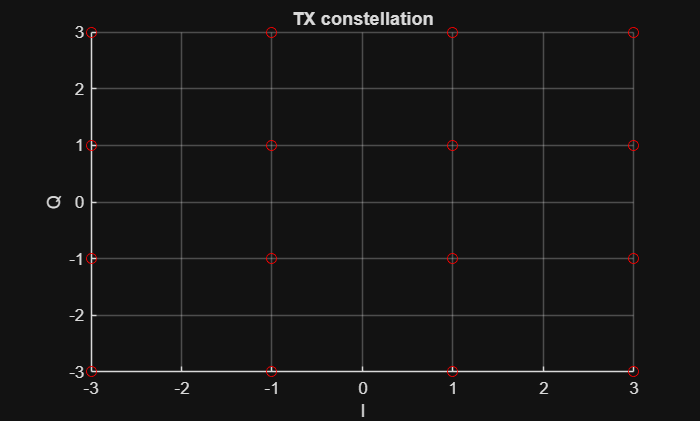

figure
title( 'TX constellation' )
hold on
grid on
plot( real( symb_TX ) , imag( symb_TX ) , 'or' )
xlabel('I')
ylabel('Q')

### Pulse shaping (TX Filtering)

#### Design of the Root Raised Cosine Filter

g = raised_cosine( rolloff , span , sps ,'sqrt' ) ;                 % Impulse Response of the Root Raised Cosine filter
gg = rcosdesign( rolloff  , span, sps ,'sqrt' ) ;                   % Impulse Response of the Root Raised Cosine filter (in-built Matlab function from the "communications" toolbox)

#### RC Impulse Response (IR) plot

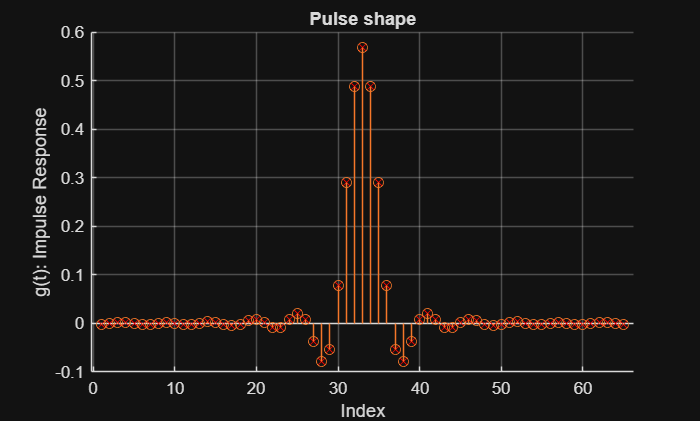

figure
title( 'Pulse shape' )
hold on
grid on
stem( g  , 'xr' )
stem( gg )
xlabel('Index')
ylabel('g(t): Impulse Response')

#### Design of the TX baseband waveform (convolution between symbol stream and RRC pulse)

signal_TX = convolution_TX( symb_TX , g , sps ) ;                   % Generation of the waveform: convolution between the RRC pulse and the symbol stream
signal_TX_test = upfirdn( symb_TX , gg , sps ) ;                    % Generation of the waveform with in-built Matlab functions
t = 0 : 1 / fs : 1 / fs * ( size( signal_TX , 1 ) - 1 ) ;           % Generation of the time vector for visualization

#### Time-domain plot of TX baseband waveform

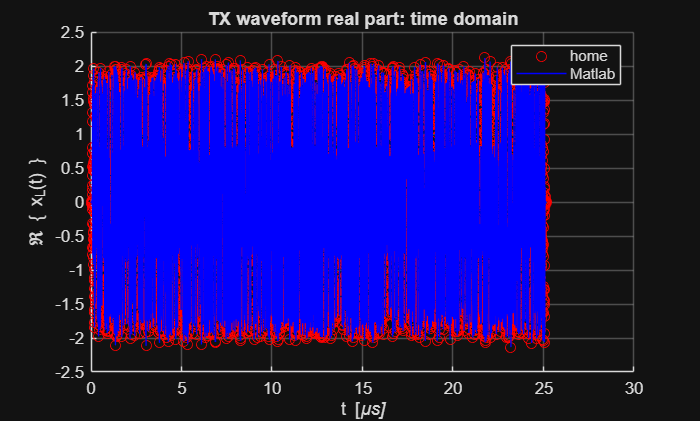

figure
title( 'TX waveform real part: time domain' )
hold on
grid on
plot( t * 1e6 , real( signal_TX )  , 'or' )
plot( t * 1e6 , real( signal_TX_test )  , 'b' )
xlabel('t [\mu\it{s}]')
ylabel('\Re \{ x_L(t) \}')
legend( 'home', 'Matlab' )

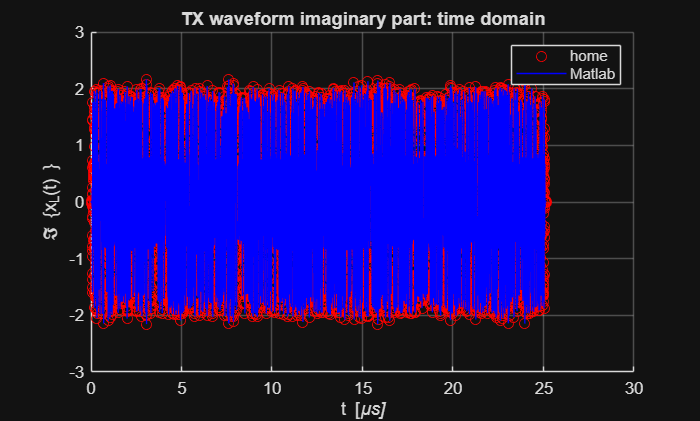


figure
title( 'TX waveform imaginary part: time domain' )
hold on
grid on
plot( t * 1e6 , imag( signal_TX )  , 'or' )
plot( t * 1e6 , imag( signal_TX_test )  , 'b' )
xlabel('t [\mu\it{s}]')
ylabel('\Im \{x_L(t) \}')
legend( 'home', 'Matlab' )

#### Spectrum plot of TX baseband waveform

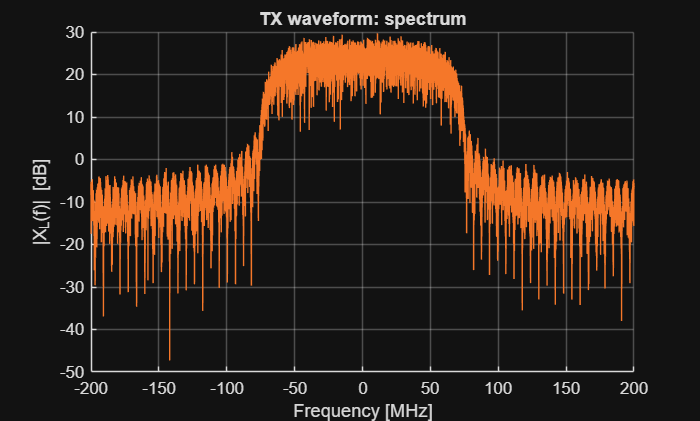

figure
title( 'TX waveform: spectrum' )
hold on
grid on
f = linspace( -fs / 2 ,  fs / 2 , length( t ) ) ;                                   % Generation of the frequency vector
plot( f * 1e-6 , 10 * log10( abs( fftshift( fft( signal_TX ) ) ) ) )
plot( f * 1e-6 , 10 * log10( abs( fftshift( fft( signal_TX_test ) ) ) ) )
xlabel('Frequency [MHz]')
ylabel('|X_{L}(f)| [dB]')

## Receiver (RX)

### Add Noise

#### Determination of received signal power

rx_mean_power = sum( abs( signal_TX ).^2 , 1 ) / length( signal_TX ) * sps  ;       % Calculation of the received mean power

#### Creating the RX thermal noise (Complex Additive White Gaussian Noise)

noise = ( randn( length( signal_TX ) , 1 ) ...
    + 1i * randn( length( signal_TX ) , 1 ) ) / sqrt( 2 ) ;                         % AWGN with unitary mean power

#### RX signal

snr = 10^( snr_dB / 10 ) ;
signal_RX = signal_TX + noise * sqrt( rx_mean_power / snr ) ;                       % Received signal + thermal noise of receiver hardware

### RX Filtering

**Tip:** check if TX and RX symbols are similar when SNR is very large (say 100dB). Use a limited number of symbols to easily visualize and therefore compare $\text{symb\_TX}$ and $\text{symb\_RX}$.

#### Convolution between received signal and RRC impulse response and sampling at symbol rate

symb_RX = convolution_RX( signal_RX , g , sps ) ;                                   % Filtering of the RX baseband waveform and sampling every pT

#### Removing the delay introduced by the TX and RX filter

symb_RX = symb_RX( span + 1 : end - span ) ;

### RX Symbols

#### Time-domain plot of TX and RX symbol streams

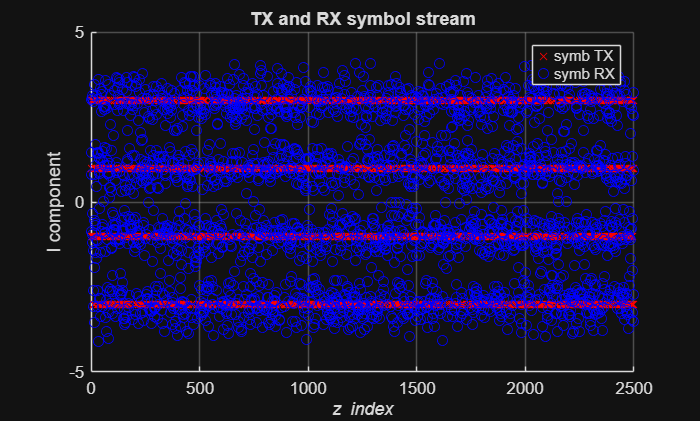

figure
title( 'TX and RX symbol stream' )
hold on
grid on
plot( real( symb_TX )  , 'xr' )
plot( real( symb_RX )  , 'ob' )
xlabel('\it{z} index')
ylabel('I component')
legend( 'symb TX', 'symb RX' )

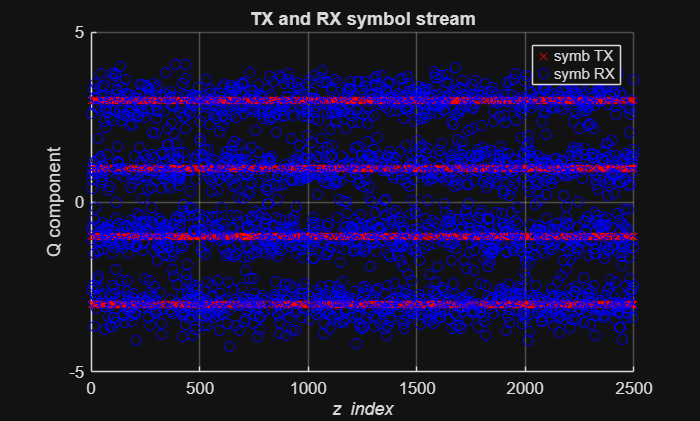


figure
title( 'TX and RX symbol stream' )
hold on
grid on
plot( imag( symb_TX )  , 'xr' )
plot( imag( symb_RX )  , 'ob' )
xlabel('\it{z} index')
ylabel('Q component')
legend( 'symb TX', 'symb RX' )

#### Received constellation plot (symbol space)

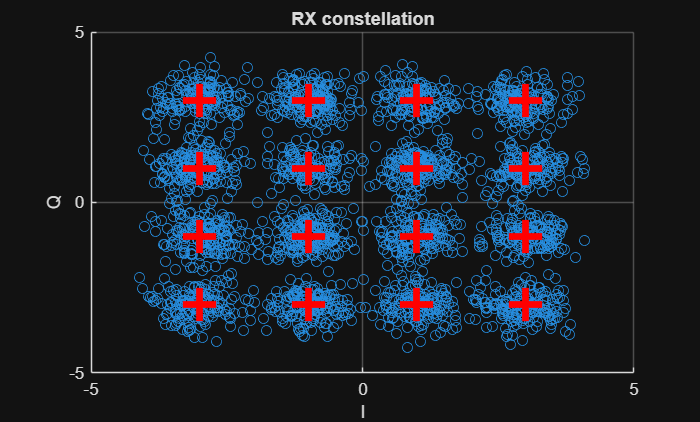

figure
title( 'RX constellation' )
hold on
grid on
plot( real( symb_RX ) , imag( symb_RX ) , 'o')
plot( real( symb_TX ) , imag( symb_TX ) , '+r' , 'MarkerSize' , 20 , 'LineWidth' , 4 )
xlabel('I')
ylabel('Q')

### Symbol Estimation

symb_RX_estimated = symbol_estimation_QAM( symb_RX , nb_bit_per_symb , nb_symb ) ;      % By observing RX symbol, make a decision on which TX symbol has been sent

### Demapping

bit_RX = demapping_QAM( symb_RX_estimated , nb_bit_per_symb , nb_symb ) ;               % Complex-symbols-to-bits demapping

## Bit Error Rate (BER) calculation

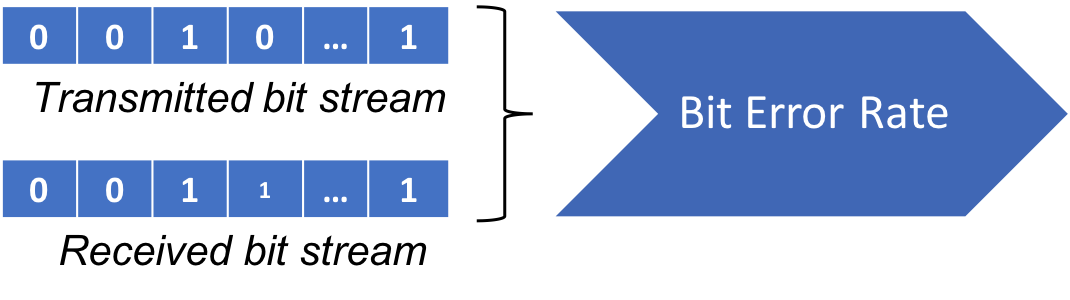

### Numerical BER calculation

- *nb_error* is the number of errors among the *nb_bit* received bits

- *ber_numerical* is the bit error rate obtained by comparing TX and RX bits

[ nb_error , ber_numerical ] = biterr( bit_TX , bit_RX )

nb_error = 34

ber_numerical = 0.0034

### Analytical BER calculation

BER analytical expressions exist for some well-known constellations. They can be used to validate your code. Several of those analytical expressions are already implemented in Matlab within the function *berawgn*.

M = 2^nb_bit_per_symb ;                                % Number of symbols in the constellation
EbNo = snr_dB - 10 * log10 ( nb_bit_per_symb ) ;       % Ratio of bit energy to noise power spectral density, in dB
ber_analytical = berawgn( EbNo , 'qam' , M )           % BER analytical expression for QAM modulation in AWGN channel

ber_analytical = 0.0045